# Multidetec

ATTENTION ! Ne fonctionne que si les cycles sont correctement recalés dans les HDD

## Accès dossier et choix essai

clear
Type = "DPMS0T";
Materiau = '7075';
Eprouvette ='3';
Numero = '1';
addpath('/home/tdelaselle/Documents/Codes/Codes-matlab/Fonctions');
repertoire_traitees = acces_donnees_traitees();
addpath(strcat(repertoire_traitees,'/',Type,'/',Materiau));
Naming = strcat(Type,'_',Materiau,'_',Eprouvette,'.',Numero);
load(strcat(Naming,'.mat'));

## Paramètres

nbreCH = 2; % Number of channels

####     Recherche de multiplets

alpha = 5; % Largeur de la zone de recherche dans le cycle de charge
nbre_cycles =50; % Nombre de cycles dans lequel s'effectue la recherche
seuil = 0.9; % Seuil minimal de corrélation
mini = 20; % Nombre minimal de WF pour qu'un multiplete soit enregistré 

####     Corrélation

pretrig = false; % Cut the pre-trigger or not
if pretrig == 1
    init = 156;
else
    init = 1;
end
impul = 300; % Choose the number of points from the beginning of the WF

###     Lancement

 
% Préparation de la table HDD

% Comptage du nombre de waveforms par channel
channel = HDD.CH;
chNbre = zeros(nbreCH,1);
chNbre(1) = length(find(channel==1));
chNbre(2) = length(find(channel==2));
chNbre(3) = length(find(channel==3));
chNbre(4) = length(find(channel==4));
chNbre(5) = length(find(channel==5));
chNbre(6) = length(find(channel==6));

clear MULTI;
HDD = sortrows(HDD,'CH');
if exist("MULTI","var");
    HDD = removevars(HDD,'MULTI');
end
alpha = alpha/100; % Passage % dans [0;1]
len = size(HDD,1);

MULTI = zeros(len,1); 
% Liste contenant les numéros des multiplets 
% ATTENTION : 
% les numéros impairs sont les multiplets du ch1
% les numéros pairs sont les multiplets du ch2

% Algo de recherche de multiplets
for c = 1:2
    K = 1*c;
    for i = (1+chNbre(1)*(c-1)):(chNbre(c)+chNbre(1)*(c-1)-1)
        j = i;
        cycleI = HDD.CYCLES(i);
        cycleJ = HDD.CYCLES(j+1);
        while (cycleJ <= cycleI+nbre_cycles+alpha) && (j<=(chNbre(c)+chNbre(1)*(c-1)-1));
            j = j+1;
            if (cycleJ-fix(cycleJ))<=(cycleI-fix(cycleI)+alpha) && (cycleJ-fix(cycleJ))>=(cycleI-fix(cycleI)-alpha) 
                test = xcorr(WF.(HDD.HDDWF(j))(init:impul),WF.(HDD.HDDWF(i))(init:impul),'normalized');
                if max(test)>seuil;
                    if MULTI(i)==0 && MULTI(j)==0
                        MULTI(i) = K;
                        MULTI(j) = K;
                        K = K+2;
                    elseif MULTI(j) == 0
                        MULTI(j) = MULTI(i);
                    elseif MULTI(i) == 0    
                        MULTI(i) = MULTI(j);
                    else
                        ind = find(MULTI==MULTI(j));
                        MULTI(ind) = MULTI(i);
                        MULTI(j) = MULTI(i);
                    end
                end
            end
            if j<=(chNbre(c)+chNbre(1)*(c-1)-1)
                cycleJ = HDD.CYCLES(j+1);                
            end
        end 
    end
end

% Suppression des multiplets en dessous du nombre mini
nbre_multi = max(MULTI);
vide = ones(nbre_multi,1);
for i = 1:nbre_multi
   ind = find(MULTI==i);
   if size(ind)<mini
       vide(i) = 0;
       MULTI(ind) = 0;
   end
end
% 'Descente' du numéro des multiplets (1,2,3,4,...) au lieu de (11,32,44,45,....) 
w = 0;
while w<nbre_multi
    w = w+1;
    if vide(w) == 1 && w>2
        v = w;
        vide(w) = 0;
        while vide(v) == 0 && v>2
            v = v-2;
        end
        vide(v+2) = 1;
        MULTI(find(MULTI==w)) = v+2;
    end
end
t = 3;
while vide(t) == 1 || vide(t+1) == 1
    if vide(t) == 1
        MULTI(find(MULTI==t)) = t-2;
        vide(t-2) = 1;
        vide(t) = 0;    
    end
    if vide(t+1) == 1
        MULTI(find(MULTI==t+1)) = t-1;
        vide(t-1) = 1;
        vide(t+1) = 0;    
    end    
    t = t+2;
end
HDD.MULTI = MULTI;
HDD = sortrows(HDD,'Time'); 

## Analyse des résultats

   Choix des variables :

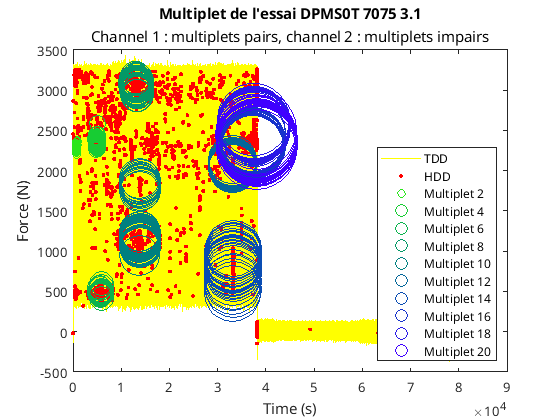

ParaX = "Time";
ParaY = "PARA1";
TDDpara1 = true;

figure();
nbre_multi = max(max(HDD.MULTI));
if TDDpara1 == 1
    plot(TDD.Time,TDD.PARA1,'y-',"DisplayName",'TDD');
end
hold on
plot(HDD.(ParaX),HDD.(ParaY),'r.','DisplayName','HDD');
xlabel(HDD.Properties.VariableDescriptions{ParaX});
ylabel(HDD.Properties.VariableDescriptions{ParaY});
legend("Location","southeast");
for i = 1:nbre_multi
    ind = find(HDD.MULTI==i);
    if isempty(ind) == 0
        plot(HDD.(ParaX)(ind),HDD.(ParaY)(ind),'o',"MarkerSize",i*3,"Color",[(0.5-i*1/(nbre_multi))^2 (1-i*1/nbre_multi) i*1/nbre_multi],'DisplayName',strcat('Multiplet'," ",string(i)));        
    end
end
% len1 = size(Multi); 
% for i = 1:len1(2)
%     l = size(Multi{i});
%     plot(HDD.(ParaX)(HDD.HDDWF==strcat(string(Channel),'_',string(Multi{i}(1)))),HDD.(ParaY)(HDD.HDDWF==strcat(string(Channel),'_',string(Multi{i}(1)))),'o',"MarkerSize",i*3,"Color",[(0.5-i*1/(len1(2)))^2 (1-i*1/len1(2)) i*1/len1(2)],'DisplayName',strcat('Cluster'," ",string(i)));
%     for j = 2:l(2)
%         h = plot(HDD.(ParaX)(HDD.HDDWF==strcat(string(Channel),'_',string(Multi{i}(j)))),HDD.(ParaY)(HDD.HDDWF==strcat(string(Channel),'_',string(Multi{i}(j)))),'o',"MarkerSize",i*3,"Color",[(0.5-i*1/(len1(2)))^2 (1-i*1/len1(2)) i*1/len1(2)]);
%         h.Annotation.LegendInformation.IconDisplayStyle = 'off';
%     end
% end
title(strcat("Multiplet de l'essai ",Type," ",Materiau," ",Eprouvette,'.',Numero));
subtitle("Channel 1 : multiplets pairs, channel 2 : multiplets impairs");
hold off

## Sauvegarde

repertoire_traitees = acces_donnees_traitees();
save(strcat('/home/tdelaselle/Documents/Données_essais/Traitement_essais/',Type,'/',Materiau,'/',Naming,'.mat'),"HDD",'-append');
Sauvegarde = "Effectuée !"

Sauvegarde = "Effectuée !"